Import data table and convert to array

load datatable.mat
data = table2array(datatable)

data = 	1.0e+03 *

    0.0010    0.1200    0.3000    0.0020    0.1180    0.7961
    0.0010    0.1200    0.3000    0.0035    0.1180    1.4769
    0.0010    0.1200    0.3000    0.0050    0.1180    1.7975
    0.0010    0.1200    0.4000    0.0020    0.1204    0.8060
    0.0010    0.1200    0.4000    0.0035    0.1204    1.4875
    0.0010    0.1200    0.4000    0.0050    0.1205    1.8221
    0.0010    0.1200    0.5000    0.0020    0.1221    0.8606
    0.0010    0.1200    0.5000    0.0035    0.1221    1.4049
    0.0010    0.1200    0.5000    0.0050    0.1221    1.9555
    0.0010    0.1400    0.3000    0.0020    0.1398    0.8128


p = data(:,1:4)';
t = data(:,5:6)';

p1 = p(1,:);
p2 = p(2,:);
p3 = p(3,:);
p4 = p(4,:);

t1 = t(1,:);
t2 = t(2,:);

p1n = (data(:,1)-min(data(:,1)))./(max(data(:,1))-min(data(:,1)));
p2n = (data(:,2)-min(data(:,2)))./(max(data(:,2))-min(data(:,2)));
p3n = (data(:,3)-min(data(:,3)))./(max(data(:,3))-min(data(:,3)));
p4n = (data(:,4)-min(data(:,4)))./(max(data(:,4))-min(data(:,4)));
t1n = (data(:,5)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));
t2n = (data(:,6)-min(data(:,6)))./(max(data(:,6))-min(data(:,6)));

pn = [p1n p2n p3n p4n]';
tn = [t1n t2n]';

for n=1:50                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net0.layers{1}.transferFcn = 'tansig';

[net0,tr0] = train(net0,pn,tn);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    12



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0026



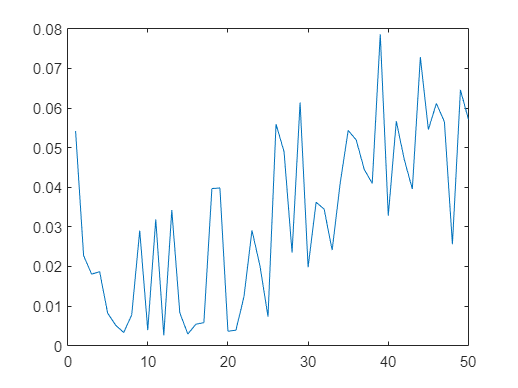

hold off;

net1 = fitnet(12,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 12
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inpu

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'tansig';

[net1,tr1] = train(net1,pn,tn);

output_ANN1 = net1(pn)

output_ANN1 =     0.4620    0.5065    0.5182    0.5232    0.5392    0.5486    0.5472    0.5352    0.5370    0.6837    0.7093    0.7257    0.7191    0.7140    0.7207    0.7327    0.7264    0.7310    0.9290    0.9281    0.9332    0.9081    0.9127    0.9120    0.9680    0.9796    0.9568    0.9792    0.9926    0.9955    0.2191    0.2078    0.2104    0.1938    0.1809    0.1819    0.3428    0.3366    0.3434    0.2866    0.2836    0.2872    0.2640    0.2658    0.2407    0.4006    0.4127    0.4002    0.4412    0.4427
    0.1762    0.5056    0.7187    0.0434    0.4756    0.7986    0.0700    0.4870    0.9498    0.1533    0.6733    0.6875    0.0367    0.4635    0.6972    0.1138    0.4634    0.8168    0.0231    0.7671    0.5267    0.0000    0.4450    0.5739    0.1897    0.4398    0.6963    0.0910    0.6232    0.5640    0.1096    0.5618    0.7359    0.1556    0.5622    0.7944    0.0534    0.8487    0.5258    0.0867    0.6428    0.6035    0.1537    0.5138    0.6892    0.0480    0.7154    0.4216    0

ANNIPF = ((output_ANN1(1,:))*(max(data(:,5))-min(data(:,5))))+min(data(:,5))

ANNIPF =   113.5575  118.2098  119.4344  119.9642  121.6362  122.6209  122.4763  121.2117  121.4073  136.7512  139.4256  141.1418  140.4580  139.9182  140.6196  141.8805  141.2199  141.6958  162.4134  162.3191  162.8522  160.2222  160.7108  160.6287  166.4866  167.7077  165.3191  167.6606  169.0631  169.3697   88.1452   86.9652   87.2401   85.5059   84.1547   84.2605  101.0907  100.4403  101.1494   95.2102   94.8921   95.2712   92.8416   93.0326   90.4096  107.1362  108.3964  107.0940  111.3852  111.5442


ANNSEA = ((output_ANN1(2,:))*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

ANNSEA = 	1.0e+03 *

    0.9917    1.4816    1.7986    0.7941    1.4371    1.9175    0.8337    1.4540    2.1424    0.9576    1.7310    1.7522    0.7842    1.4190    1.7666    0.8989    1.4189    1.9446    0.7640    1.8707    1.5130    0.7296    1.3915    1.5833    1.0118    1.3838    1.7653    0.8649    1.6566    1.5685    0.8926    1.5653    1.8241    0.9611    1.5658    1.9113    0.8090    1.9920    1.5116    0.8586    1.6858    1.6273    0.9582    1.4938    1.7548    0.8009    1.7937    1.3568    0.7669    1.7595


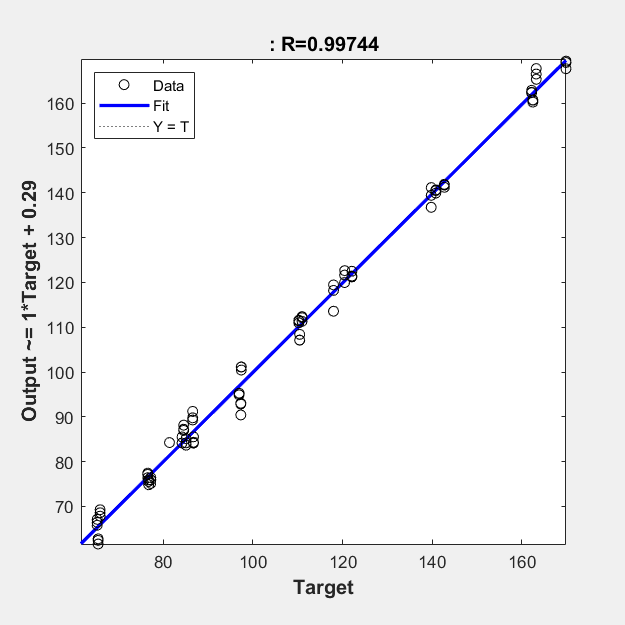

plotregression(t1,ANNIPF)

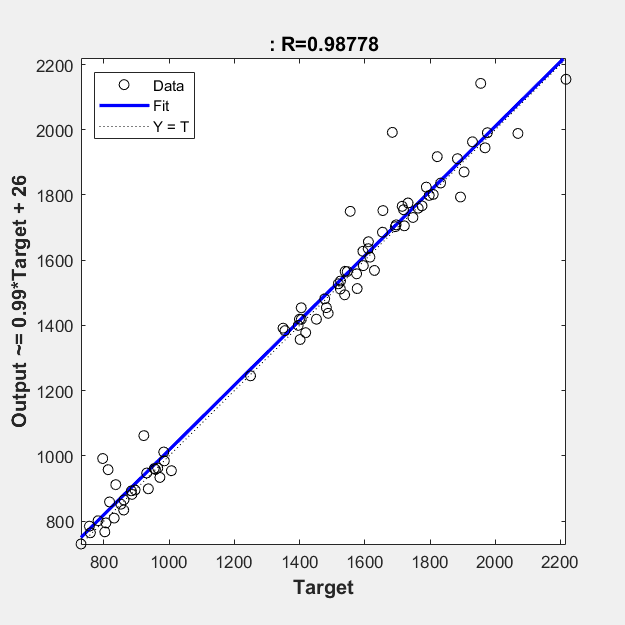

plotregression(t2,ANNSEA)